
$$\frac{d^2 }{\textrm{d}t^2 }y-4y=0$$


y(0)=1

y(1)=3

% f = ?
% y'= z
M= [0 1; 4 0];
f1 = @(t,yz) [yz(2); 4*yz(1)];
f2 = @(t,yz) M*[yz(2); yz(1)];
a=0;
b=1;
ya=1;
yb=3;
h=0.01;
d = shootingF(f1,0,1,1,3,0.01,0)

d = 0.6886

d = shootingF(f1,0,1,1,3,0.01,-1)

d = -1.0894


g = @(s) shootingF(f1,a,b,ya,yb,h,s)

g = function_handle with value:
    @(s)shootingF(f1,a,b,ya,yb,h,s)


g(0)

ans = 0.6886

g(-1)

ans = -1.0894

[s, i] = biseccion(g,0,-1)

s =   -0.387306110873280


i =     50


y0= [ya;s]

y0 =    1.000000000000000
  -0.387306110873280


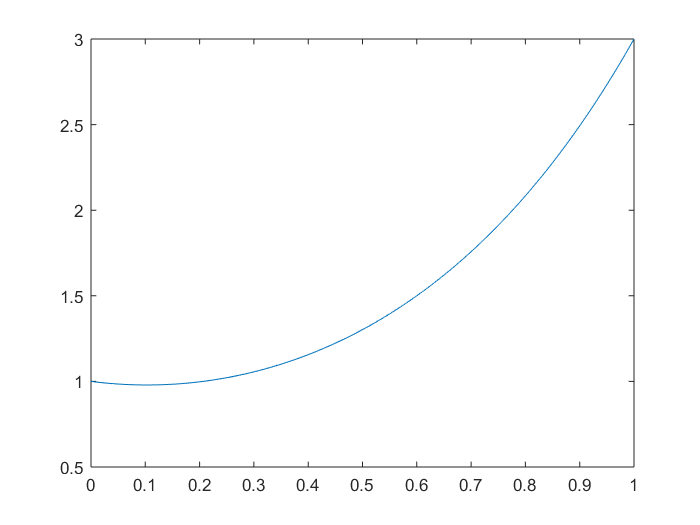

[t,y] = ivps(f1,a,y0,h,b,'euler');
plot(t,y(1,:));